This is the dynamic model of the MyPAM. Work needs to be done to add accuracy.

% This is the dynamic model of the myPAM.


clc; %clear the command window.
clear; % clear the workspace.


%initilise lengths.
L0 = 0.3; %meters.
L1 = 0.25; %meters.

%Initialse angles.
T0_deg = 0; %degrees.
T1_deg = 90; % degrees.
T0_rad = deg2rad(T0_deg); % radians.
T1_rad = deg2rad(T1_deg); % radians.


This is the provisional layout for the Centres of Mass. This will need to be adjusted according to a better analysis of the components. 

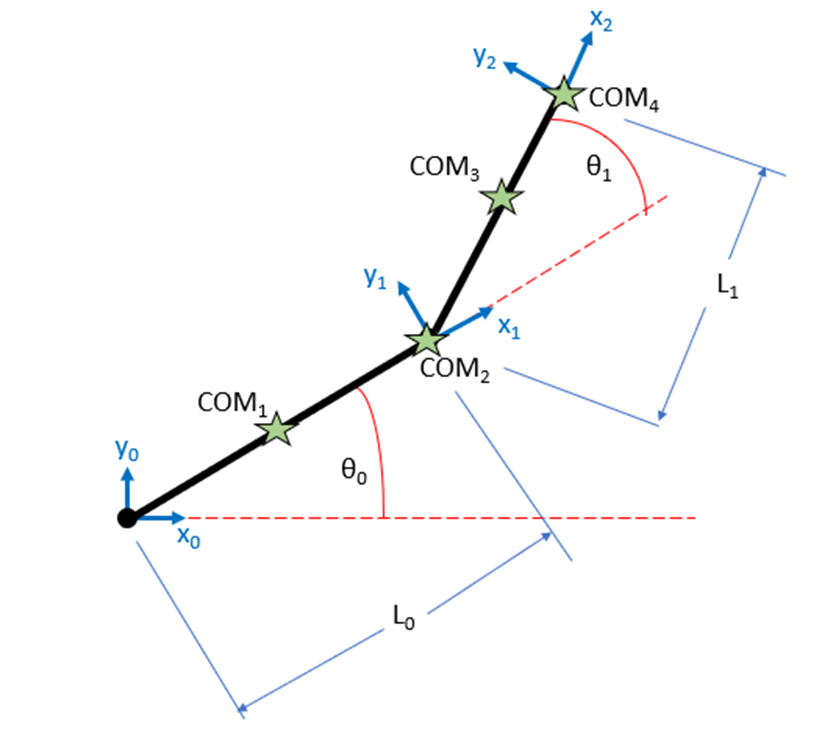

Where:

COM1 = Centre of mass of Link L0.

COM2 = Centre of mass of Joint J1 (motor and gearbox).

COM3 = Centre of mass of Link L1.

COM4 = Centre of mass of end effector.

% Initialise Jacobian matrices for COMs in cartesian space. Note, this will
% be required every iteration of the loop, thus it is necessary to use
% functions

    %Initialise COM1 Jacobian, J_theta_COM1
    J_theta_COM1 = J_theta_COM1(L0,T0_rad);
    
    %Initialise COM2 Jacobian, J_theta_COM2
    J_theta_COM2 = J_theta_COM2(L0,T0_rad);
    
    %Initialise COM3 Jacobian, J_theta_COM3
    J_theta_COM3 = J_theta_COM3(L0,L1,T0_rad,T1_rad);

    %Initialise end effector Jacobian (COM4), J_ee_theta
    J_ee_theta = J_ee_theta(L0,L1,T0_rad,T1_rad);

Its necessary to initialise a mass/inertia matrix in cartesian space for each COM. These will be later combined to create a single mass/inertia matrix in joint space. Each COM mass matrix takes the form:


$${\mathit{\mathbf{M}}}_{\mathit{\mathbf{x}}\mathit{\mathbf{i}}} {\left(\theta \right)}={\left[\begin{array}{cccccc}
m_i  & 0 & 0 & 0 & 0 & 0\\
0 & m_i  & 0 & 0 & 0 & 0\\
0 & 0 & m_i  & 0 & 0 & 0\\
0 & 0 & 0 & I_{xx}  & I_{xy}  & I_{xz} \\
0 & 0 & 0 & I_{yx}  & I_{yy}  & I_{yz} \\
0 & 0 & 0 & I_{zx}  & I_{zy}  & I_{zz} 
\end{array}\right]}$$


% Initialise the Mass Matrices in cartesian space for each COM. Note, this
% only needs to be done once, therefore no functions need to be created for
% this.

    %Initialise COM1 Cartesian Mass Matrix, M_x1
    M_x1 = [];
    
    %Initialise COM2 Cartesian Mass Matrix, M_x2
    M_x2 = [];
    
    %Initialise COM3 Cartesian Mass Matrix, M_x3
    M_x3 = [];

    %Initialise COM4 Cartesian Mass Matrix, M_x4
    M_x4 = [];
    

The single mass matrix in joint space can now be defined. This will be required during each iteration of the loop so a function must be created. The equation takes the form:


$$\mathit{\mathbf{M}}{\left(\theta \right)}=\sum_{i=0}^n {\left({{\mathit{\mathbf{J}}}_{\mathit{\mathbf{i}}} }^{\mathit{\mathbf{T}}} \left(\theta \right){\mathit{\mathbf{M}}}_{\mathit{\mathbf{x}}\mathit{\mathbf{i}}} \left(\theta \right){\mathit{\mathbf{J}}}_{\mathit{\mathbf{i}}} \left(\theta \right)\right)}$$


%Initialise the Mass matrix in joint space. Note that this is a fucntion since it will be called every iteration of the loop.    
M_theta = M_theta(J_theta_COM1,J_theta_COM2,J_theta_COM4,J_ee_theta,M_x1,M_x2,M_x3,M_x4);
    